# 04 Homework: Thermal Conduction

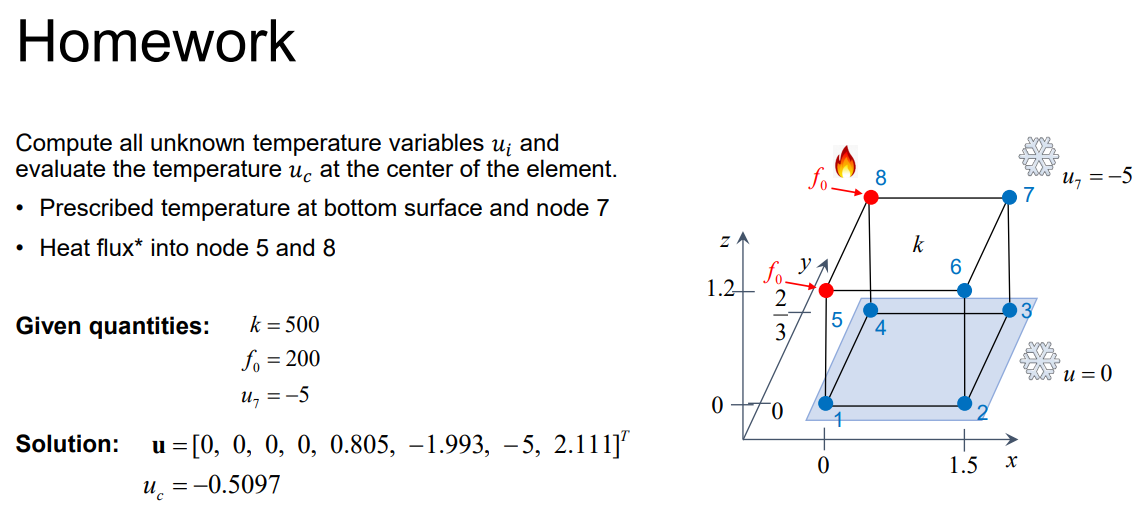

clc; clear all; close all;

% Given parameters
lx = 1.5;
ly = 2/3;
lz = 1.2;
k = 500;


% Set up GLOBAL nodes and elements
nodes = [0, 0, 0;
         lx, 0, 0;
         lx, ly, 0;
         0, ly, 0;
         0, 0, 1;
         lx, 0, 1;
         lx, ly, 1;
         0, ly, 1];

nNodes = size(nodes, 1);
dofPerNode = 1;


% GLOBAL notes for each element (counterclockwise)
elements = [1,2,3,4,5,6,7,8];   % element 1

nElements = size(elements, 1);
dofPerElement = dofPerNode * size(elements, 2); % dofPerNode * NodesPerElement

% Set up system matrices
K = zeros(nNodes * dofPerNode);
u = zeros(nNodes * dofPerNode, 1);
f = zeros(nNodes * dofPerNode, 1);

% Integrate stiffness by looping over elements
[xg, wg] = gaussianPoints3D(); % second order & 3d
for e = 1 : nElements
    KE = zeros(dofPerElement);
    % fE = zeros(dofPerElement, 1);

    xmin = 0;
    xmax = lx;
    ymin = 0;
    ymax = ly;
    zmin = 0;
    zmax = lz;

    % Integrate stiffness using Gauss quadrature
    for g = 1 : size(xg, 1)
        % Map integration point from standard space (r, s) to cartesian coordinates (x, y)
        xgi(1) = 0.5 * (xmax - xmin) * xg(g,1) + ...
                 0.5 * (xmin + xmax);
        xgi(2) = 0.5 * (ymax - ymin) * xg(g,2) + ...
                 0.5 * (ymin + ymax);
        xgi(3) = 0.5 * (zmax - zmin) * xg(g,3) + ...
                 0.5 * (zmin + zmax);

        % Evaluate shape function gradients at integration point b
        dh = shapeFunctionGradients(xmin, xmax, ymin, ymax, zmin, zmax, xgi);

        % Evaluate summand for quadrature of element stiffness matrix
        KE = KE + k * (dh' * dh);
    end
    % Mapping from xy to rs space
    KE = (xmax - xmin) / 2 * ...
         (ymax - ymin) / 2 * ...
         (zmax - zmin) / 2 * ...
         KE;

    % Use element connectivity to add element stiffness to global stiffness matrix
    K(elements(e, :), elements(e, :)) = K(elements(e, :), elements(e, :)) + KE;
end

% Prescribed temperature on node 8
u(1:4)  = 0;
u(7)    = -5;

f([5,8]) = 200;
f = f  ...
        - u(1) * K(:, 1) ... % not necessary u1 = 0
        - u(2) * K(:, 2) ... % not necessary u2 = 0
        - u(3) * K(:, 3) ... % not necessary u3 = 0
        - u(4) * K(:, 4) ... % not necessary u4 = 0
        - u(7) * K(:, 7);

% Solve system
fixeddofs = [1, 2, 3, 4, 7];
freedofs = setdiff(1 : 8, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs)

u =          0
         0
         0
         0
    0.8047
   -1.9926
   -5.0000
    2.1106


## u_c 

temperature at the center of the element

xmin = 0;
xmax = lx;
ymin = 0;
ymax = ly;
zmin = 0;
zmax = lz;


fhDisplacement = @(x, y, z) displacementField(u, xmin, xmax, ymin, ymax, zmin, zmax, x, y, z);
fhDisplacement(lx/2, ly/2, lz/2)

ans = -0.5097

function uOut = displacementField(u, xmin, xmax, ymin, ymax, zmin, zmax, x, y, z)
    %{
        Compute state variable u from nodal variables, interpolated using shape functions
        INPUT
          u (array)       Nodal variables for element in local order
          xmin (scalar)   Minimum x coordinate for element
          xmax (scalar)   Maximum x coordinate for element
          ymin (scalar)   Minimum y coordinate for element
          ymax (scalar)   Maximum y coordinate for element
          x (array)       x coordinate(s) for evaluation of u
          y (array)       y coordinate(s) for evaluation of u
        OUTPUT
          uout (array)    Variable u for given x and y in element
    %}

    uOut = zeros(size(x));
    h = shapeFunctions(xmin, xmax, ymin, ymax, zmin, zmax, [x(:), y(:), z(:)]);
    for i = 1 : numel(x)
        uOut(i) = h(i, :) * u;
    end
end



function h = shapeFunctions(xmin, xmax, ymin, ymax, zmin, zmax, x)
    %{
        Evaluate shape functions for rectangular element at x in cartesian coordinates
        INPUT
          xmin (scalar)       Minimum x coordinate for element
          xmax (scalar)       Maximum x coordinate for element
          ymin (scalar)       Minimum y coordinate for element
          ymax (scalar)       Maximum y coordinate for element
          x (array)           Point(s) for evaluation of shape functions in cartesian coordinates
    %}

    V = (xmax - xmin) * (ymax - ymin) * (zmax - zmin);

    % Evaluate shape functions
    h(:, 1) = 1/V * (xmax - x(:, 1)) .* (ymax - x(:, 2)) .* (zmax - x(:,3));
    h(:, 2) = 1/V * (x(:, 1) - xmin) .* (ymax - x(:, 2)) .* (zmax - x(:,3));
    h(:, 3) = 1/V * (x(:, 1) - xmin) .* (x(:, 2) - ymin) .* (zmax - x(:,3));
    h(:, 4) = 1/V * (xmax - x(:, 1)) .* (x(:, 2) - ymin) .* (zmax - x(:,3));
    h(:, 5) = 1/V * (xmax - x(:, 1)) .* (ymax - x(:, 2)) .* (x(:,3) - zmin);
    h(:, 6) = 1/V * (x(:, 1) - xmin) .* (ymax - x(:, 2)) .* (x(:,3) - zmin);
    h(:, 7) = 1/V * (x(:, 1) - xmin) .* (x(:, 2) - ymin) .* (x(:,3) - zmin);
    h(:, 8) = 1/V * (xmax - x(:, 1)) .* (x(:, 2) - ymin) .* (x(:,3) - zmin);
end



function dh = shapeFunctionGradients(xmin, xmax, ymin, ymax, zmin, zmax, X)
    %{
        Evaluate shape function gradients for rectangular element at x in cartesian coordinates
        INPUT
          xmin (scalar)       Minimum x coordinate for element
          xmax (scalar)       Maximum x coordinate for element
          ymin (scalar)       Minimum y coordinate for element
          ymax (scalar)       Maximum y coordinate for element
          x (array)           Point(s) for evaluation of shape functions in cartesian coordinates
    %}

    V = (xmax - xmin) * (ymax - ymin) * (zmax - zmin) ;

    x = X(1,1);
    y = X(1,2);
    z = X(1,3);

    dh(1:3, 1) = 1/V * [-(ymax-y)*(zmax-z) ; 
                        -(xmax-x)*(zmax-z) ; 
                        -(xmax-x)*(ymax-y)];
    dh(1:3, 2) = 1/V * [ (ymax-y)*(zmax-z) ; 
                        -(x-xmin)*(zmax-z) ; 
                        -(x-xmin)*(ymax-y)];
    dh(1:3, 3) = 1/V * [ (y-ymin)*(zmax-z) ; 
                         (x-xmin)*(zmax-z) ; 
                        -(x-xmin)*(y-ymin)];
    dh(1:3, 4) = 1/V * [-(y-ymin)*(zmax-z) ; 
                         (xmax-x)*(zmax-z) ; 
                        -(xmax-x)*(y-ymin)];
    dh(1:3, 5) = 1/V * [-(ymax-y)*(z-zmin) ; 
                        -(xmax-x)*(z-zmin) ; 
                         (xmax-x)*(ymax-y)];
    dh(1:3, 6) = 1/V * [ (ymax-y)*(z-zmin) ; 
                        -(x-xmin)*(z-zmin) ; 
                         (x-xmin)*(ymax-y)];
    dh(1:3, 7) = 1/V * [ (y-ymin)*(z-zmin) ; 
                         (x-xmin)*(z-zmin) ; 
                         (x-xmin)*(y-ymin)];
    dh(1:3, 8) = 1/V * [-(y-ymin)*(z-zmin) ; 
                         (xmax-x)*(z-zmin) ; 
                         (xmax-x)*(y-ymin)];
end

